## **Driver test program to check Clothoids library**

**Test G2 clothoid**

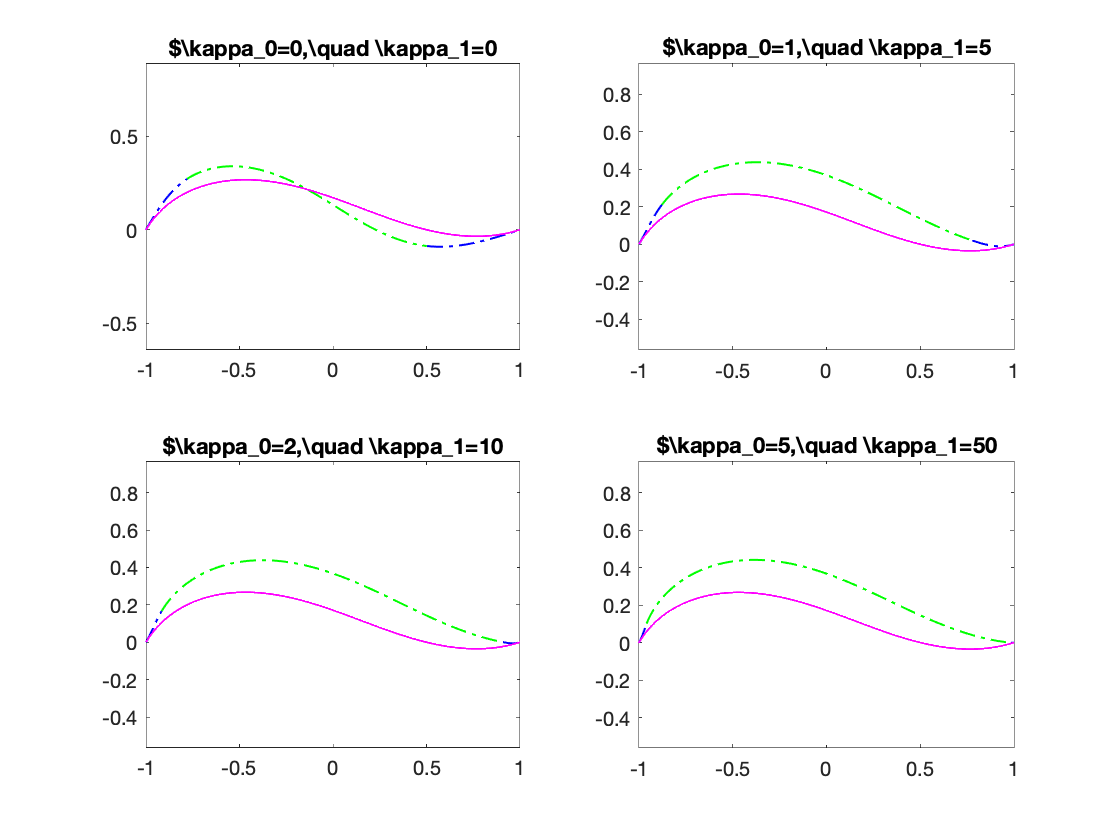

close all;
format long;
x0 = -1;
y0 = 0;
x1 = 1;
y1 = 0;

theta0 = pi/3;
kappa0 = [0,1,2,5,10];
theta1 = pi/10;
kappa1 = [0,5,10,50,200];

close all;
figure(1);

S = ClothoidList();
C = ClothoidCurve();

for k=1:4
  %subaxis(2,2,k, 'Spacing', 0.02, 'Padding', 0.04, 'Margin', 0.02);
  %axis tight;
  subplot(2,2,k);
  iter = S.build_3arcG2(x0,y0,theta0,kappa0(k),x1,y1,theta1,kappa1(k));
  if iter >= 0
    S.plot(1000,{'-.g','Linewidth',1},{'-.b','Linewidth',1});
    hold on
    axis equal;
    iter = C.build_G1(x0,y0,theta0,x1,y1,theta1);
    C.plot(1000,'-m','Linewidth',1);
  else
    disp('errore');
  end
  title( sprintf('$\\kappa_0=%g,\\quad \\kappa_1=%g%s$',kappa0(k),kappa1(k)),...
         'Interpreter','none'); 
  set(gca,'DataAspectRatio',[1,1,1]);
  if false
    set(gca,'XTick',[-2,-1.5,-1,-0.5,0,0.5,1,1.5,2]);
    set(gca,'XTickLabel',{'$-2$','$-1.5$','$-1$','$-0.5$','$0$','$0.5$','$1$','$1.5$','$2$'});
    set(gca,'YTick',[-2,-1.5,-1,-0.5,0,0.5,1,1.5,2]);
    set(gca,'YTickLabel',{'$-2$','$-1.5$','$-1$','$-0.5$','$0$','$0.5$','$1$','$1.5$','$2$'});
  end
end